## **HCP Main Sample - Whole-Brain Coupling Plot Across Conditions**

Computation of coupling measure-specific brain-average coupling values for all eight conditions, taking the mean across the four measure-specific brain-average coupling values per condition and creating the violin plot visualizing condition-specific differences in brain-average SC-FC coupling. Run ANOVA to test for significant differences between brain-average condition-specific SC-FC coupling.

Before running this script: 

- run all scripts in HCP Data Prep 

**1. Compute brain-average coupling values **

1.1. Resting-state 

for i = 1:532
    whole_brain_values_HCP_rest{i,1} = mean(final_r_all_HCP_rest_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_rest{i,2} = mean(final_r_all_HCP_rest_532{i,1}(:,2));% G 
    whole_brain_values_HCP_rest{i,3} = mean(final_r_all_HCP_rest_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_rest{i,4} = mean(final_r_all_HCP_rest_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_rest_table = cell2table(whole_brain_values_HCP_rest);
 whole_brain_values_HCP_rest_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_rest_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.26241    0.26921    0.28842    0.20958
    0.26472    0.27125    0.28796    0.16062
    0.28671    0.29102     0.3157     0.2594
    0.25345    0.25433    0.27388    0.22293
    0.30403    0.29867    0.32095    0.25023
    0.30824    0.32697    0.34864    0.30061
    0.29297     0.2847    0.30774     0.2275
     0.2587    0.27543     0.2901    0.22258
    0.28783    0.28327    0.30911    0.26172
    0.28416    0.29294    0.30979    0.21278
    0.29607     0.3054    0.32864    0.23963
     0.3242    0.32659    0.35901    0.28468
    0.28998    0.28396     0.3105    0.22044
    0.26265    0.28207    0.29989    0.21407
    0.28991    0.29946     0.3166    0.23476
    0.25791     0.2755    0.29123     0.2126


1.2. Emotion processing (176 frames)

for i = 1:532
    whole_brain_values_HCP_emotion{i,1} = mean(final_r_all_HCP_emotion_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_emotion{i,2} = mean(final_r_all_HCP_emotion_532{i,1}(:,2));% G 
    whole_brain_values_HCP_emotion{i,3} = mean(final_r_all_HCP_emotion_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_emotion{i,4} = mean(final_r_all_HCP_emotion_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_emotion_table = cell2table(whole_brain_values_HCP_emotion);
 whole_brain_values_HCP_emotion_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_emotion_table = 532×4 table
      Pl          G         Cos         SI   
    _______    _______    _______    ________

    0.15874    0.18069    0.18416      0.1281
    0.17971    0.18118    0.19089     0.13498
    0.16282    0.16631    0.16981     0.13584
    0.11691    0.12941    0.12784    0.092762
    0.18926    0.17597    0.18696     0.15995
    0.15549    0.16715    0.17083      0.1412
    0.15393    0.15751    0.15502     0.11522
    0.20942     0.2074    0.22418     0.19199
    0.13149    0.13353    0.13596     0.10859
     0.1549    0.16317    0.16582     0.12122
     0.1729    0.18002    0.18078     0.14643
    0.18051    0.18957    0.19886     0.15811
    0.16788    0.18257    0.18569     0.12053
    0.13297    0.15542    0.14547    0.091491
    0.16904    0.17487    0.17824     0.12873
    0.18934     0.1876    0.20

1.3. Gambling (253 frames)

for i = 1:532
    whole_brain_values_HCP_gambling{i,1} = mean(final_r_all_HCP_gambling_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_gambling{i,2} = mean(final_r_all_HCP_gambling_532{i,1}(:,2));% G 
    whole_brain_values_HCP_gambling{i,3} = mean(final_r_all_HCP_gambling_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_gambling{i,4} = mean(final_r_all_HCP_gambling_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_gambling_table = cell2table(whole_brain_values_HCP_gambling);
 whole_brain_values_HCP_gambling_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_gambling_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.19335    0.21377     0.2155    0.16249
    0.19885    0.20184    0.20869     0.1222
    0.21984    0.22077    0.22975    0.20427
    0.16632    0.18043    0.17986     0.1341
    0.23102    0.23672    0.24824    0.19149
    0.20468    0.21825     0.2221    0.18572
    0.21935    0.21034    0.21649    0.17667
    0.20181    0.21335      0.219    0.17721
    0.20394    0.20226     0.2133    0.17234
    0.19121    0.20003    0.20073    0.14938
    0.23787     0.2419    0.25002    0.20178
    0.24564    0.25902    0.27315     0.2026
    0.20317    0.21969    0.21809    0.14788
    0.21812    0.23659    0.23759    0.17423
     0.2333    0.24052    0.24947    0.18886
    0.22348    0.23465     0.2428     0.1861


1.4. Language (316 frames)

for i = 1:532
    whole_brain_values_HCP_language{i,1} = mean(final_r_all_HCP_language_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_language{i,2} = mean(final_r_all_HCP_language_532{i,1}(:,2));% G 
    whole_brain_values_HCP_language{i,3} = mean(final_r_all_HCP_language_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_language{i,4} = mean(final_r_all_HCP_language_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_language_table = cell2table(whole_brain_values_HCP_language);
 whole_brain_values_HCP_language_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_language_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.23125    0.24837    0.25979    0.19057
    0.26861    0.27301    0.28915    0.18894
    0.24599    0.25279    0.26061    0.21081
    0.20501    0.22562    0.23267    0.15728
    0.24057    0.24402    0.25761    0.18531
    0.26923    0.27437    0.28811    0.23758
    0.22293    0.22587    0.23326    0.15435
    0.24359    0.24789    0.26384    0.19607
    0.27781    0.26875     0.2932    0.23541
    0.25931    0.25899    0.27663    0.20737
    0.24011    0.26717    0.26707    0.16977
    0.24529    0.26123    0.27648    0.20221
    0.22784    0.25427    0.25482    0.14288
    0.24406    0.26842    0.27258    0.17955
    0.22385    0.24398      0.243    0.15912
     0.2733    0.26705     0.2875    0.22969


1.5. Motor (284 frames)

for i = 1:532
    whole_brain_values_HCP_motor{i,1} = mean(final_r_all_HCP_motor_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_motor{i,2} = mean(final_r_all_HCP_motor_532{i,1}(:,2));% G 
    whole_brain_values_HCP_motor{i,3} = mean(final_r_all_HCP_motor_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_motor{i,4} = mean(final_r_all_HCP_motor_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_motor_table = cell2table(whole_brain_values_HCP_motor);
 whole_brain_values_HCP_motor_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_motor_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.21296    0.21882    0.23168       0.16
    0.21753     0.2216    0.22654    0.14892
    0.21657    0.21377    0.21798     0.1834
    0.18294    0.19344    0.19497    0.15645
    0.21586    0.20767    0.21016    0.16856
    0.21604    0.22845    0.23214    0.18362
     0.1917    0.18832    0.19951     0.1581
    0.19371    0.20696    0.21247    0.16014
    0.18691      0.189    0.19956    0.15669
    0.18443    0.19468    0.19856    0.14163
    0.21703    0.22455     0.2291    0.16899
    0.23763    0.23915    0.25339    0.19668
    0.19346    0.19961    0.19984    0.12872
    0.21464     0.2226    0.22996    0.17338
    0.19314    0.20186    0.20472    0.15257
    0.21632    0.22207    0.22967    0.19032


1.6. Relational (232 frames)

for i = 1:532
    whole_brain_values_HCP_relational{i,1} = mean(final_r_all_HCP_relational_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_relational{i,2} = mean(final_r_all_HCP_relational_532{i,1}(:,2));% G 
    whole_brain_values_HCP_relational{i,3} = mean(final_r_all_HCP_relational_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_relational{i,4} = mean(final_r_all_HCP_relational_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_relational_table = cell2table(whole_brain_values_HCP_relational);
 whole_brain_values_HCP_relational_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_relational_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.20417    0.23185    0.23351    0.15225
    0.21111    0.22374    0.23086     0.1362
    0.22722    0.22828    0.23872    0.20823
    0.17735    0.18916    0.18851    0.14109
    0.18823    0.19213      0.195    0.15866
    0.20219    0.21948     0.2272    0.17958
     0.2053    0.20659    0.21025    0.16441
    0.20991    0.21304    0.22834    0.19893
     0.2046    0.20425    0.21265    0.17393
    0.23025    0.24129    0.24708    0.18222
    0.22936    0.24234     0.2474     0.1935
    0.25399    0.25555    0.27489    0.20923
     0.1873    0.21297    0.21039    0.13197
    0.20203    0.21876    0.21981    0.16051
    0.23712    0.24758    0.26111    0.21001
    0.24761     0.2528     0.2654    0.19837

1.7. Social (274 frames)

for i = 1:532
    whole_brain_values_HCP_social{i,1} = mean(final_r_all_HCP_social_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_social{i,2} = mean(final_r_all_HCP_social_532{i,1}(:,2));% G 
    whole_brain_values_HCP_social{i,3} = mean(final_r_all_HCP_social_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_social{i,4} = mean(final_r_all_HCP_social_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_social_table = cell2table(whole_brain_values_HCP_social);
 whole_brain_values_HCP_social_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_social_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.20427    0.23935     0.2436    0.16756
    0.22911    0.24716    0.25299    0.15463
    0.21756    0.23493    0.23864    0.18277
    0.18347    0.20058     0.2031    0.15604
    0.23466     0.2426    0.26051    0.21153
    0.21337    0.23565    0.23704    0.18782
    0.17826    0.20319    0.20068    0.11304
    0.23371    0.23908    0.25272    0.20974
    0.23085    0.23774    0.24789    0.18635
    0.19562    0.22312    0.22955    0.13954
    0.23788     0.2518    0.26197    0.20178
    0.23186    0.25789    0.27445    0.21211
    0.22611    0.24868    0.25637    0.17394
    0.18973    0.22637    0.21303    0.13303
    0.21325    0.24138    0.24552    0.17015
    0.23844    0.25218    0.26455    0.20931


1.8. WM (405 frames)

for i = 1:532
    whole_brain_values_HCP_wm{i,1} = mean(final_r_all_HCP_wm_532{i,1}(:,1));% Pl
    whole_brain_values_HCP_wm{i,2} = mean(final_r_all_HCP_wm_532{i,1}(:,2));% G 
    whole_brain_values_HCP_wm{i,3} = mean(final_r_all_HCP_wm_532{i,1}(:,3));% Cos
    whole_brain_values_HCP_wm{i,4} = mean(final_r_all_HCP_wm_532{i,1}(:,4));% SI 
   
end

Convert cell to table 

 whole_brain_values_HCP_wm_table = cell2table(whole_brain_values_HCP_wm);
 whole_brain_values_HCP_wm_table.Properties.VariableNames = {'Pl', 'G', 'Cos', 'SI'}

whole_brain_values_HCP_wm_table = 532×4 table
      Pl          G         Cos        SI   
    _______    _______    _______    _______

    0.22729    0.25821    0.25872    0.17912
    0.22539     0.2406    0.24439    0.16424
     0.2365     0.2491    0.25446    0.20201
    0.20176    0.22034    0.21169    0.17106
    0.25974    0.26576    0.27205    0.22287
    0.24268    0.26264     0.2698    0.23313
    0.23561    0.23575    0.23633    0.17257
    0.23709    0.25176    0.26438     0.2123
    0.21289    0.22301    0.22492     0.1792
    0.21779    0.22855     0.2306    0.17205
    0.26224     0.2709    0.28437    0.22876
    0.27817    0.28201    0.29996    0.23872
    0.22159    0.24562    0.23963     0.1533
    0.23234    0.26205    0.25844    0.18271
    0.27711    0.27188    0.28799     0.2357
    0.26027    0.26315    0.27527    0.21346


**2. Average coupling measures within the conditions **

2.1. Take average across all resting-state values 

Rest_values_from_all_measures = [whole_brain_values_HCP_rest_table.Pl whole_brain_values_HCP_rest_table.G whole_brain_values_HCP_rest_table.Cos whole_brain_values_HCP_rest_table.SI]

Rest_values_from_all_measures =     0.2624    0.2692    0.2884    0.2096
    0.2647    0.2712    0.2880    0.1606
    0.2867    0.2910    0.3157    0.2594
    0.2535    0.2543    0.2739    0.2229
    0.3040    0.2987    0.3210    0.2502
    0.3082    0.3270    0.3486    0.3006
    0.2930    0.2847    0.3077    0.2275
    0.2587    0.2754    0.2901    0.2226
    0.2878    0.2833    0.3091    0.2617
    0.2842    0.2929    0.3098    0.2128


Rest_all = mean(Rest_values_from_all_measures,2)

Rest_all =     0.2574
    0.2461
    0.2882
    0.2511
    0.2935
    0.3211
    0.2782
    0.2617
    0.2855
    0.2749


2.2. Take average across all emotion processing values 

Emotion_values_from_all_measures = [whole_brain_values_HCP_emotion_table.Pl whole_brain_values_HCP_emotion_table.G whole_brain_values_HCP_emotion_table.Cos whole_brain_values_HCP_emotion_table.SI]

Emotion_values_from_all_measures =     0.1587    0.1807    0.1842    0.1281
    0.1797    0.1812    0.1909    0.1350
    0.1628    0.1663    0.1698    0.1358
    0.1169    0.1294    0.1278    0.0928
    0.1893    0.1760    0.1870    0.1599
    0.1555    0.1671    0.1708    0.1412
    0.1539    0.1575    0.1550    0.1152
    0.2094    0.2074    0.2242    0.1920
    0.1315    0.1335    0.1360    0.1086
    0.1549    0.1632    0.1658    0.1212


Emotion_all = mean(Emotion_values_from_all_measures,2)

Emotion_all =     0.1629
    0.1717
    0.1587
    0.1167
    0.1780
    0.1587
    0.1454
    0.2082
    0.1274
    0.1513


2.3. Take average across all gambling values 

Gambling_values_from_all_measures = [whole_brain_values_HCP_gambling_table.Pl whole_brain_values_HCP_gambling_table.G whole_brain_values_HCP_gambling_table.Cos whole_brain_values_HCP_gambling_table.SI]

Gambling_values_from_all_measures =     0.1934    0.2138    0.2155    0.1625
    0.1989    0.2018    0.2087    0.1222
    0.2198    0.2208    0.2297    0.2043
    0.1663    0.1804    0.1799    0.1341
    0.2310    0.2367    0.2482    0.1915
    0.2047    0.2183    0.2221    0.1857
    0.2194    0.2103    0.2165    0.1767
    0.2018    0.2133    0.2190    0.1772
    0.2039    0.2023    0.2133    0.1723
    0.1912    0.2000    0.2007    0.1494


Gambling_all = mean(Gambling_values_from_all_measures,2)

Gambling_all =     0.1963
    0.1829
    0.2187
    0.1652
    0.2269
    0.2077
    0.2057
    0.2028
    0.1980
    0.1853


2.4. Take average across all language values 

Language_values_from_all_measures = [whole_brain_values_HCP_language_table.Pl whole_brain_values_HCP_language_table.G whole_brain_values_HCP_language_table.Cos whole_brain_values_HCP_language_table.SI]

Language_values_from_all_measures =     0.2312    0.2484    0.2598    0.1906
    0.2686    0.2730    0.2891    0.1889
    0.2460    0.2528    0.2606    0.2108
    0.2050    0.2256    0.2327    0.1573
    0.2406    0.2440    0.2576    0.1853
    0.2692    0.2744    0.2881    0.2376
    0.2229    0.2259    0.2333    0.1543
    0.2436    0.2479    0.2638    0.1961
    0.2778    0.2688    0.2932    0.2354
    0.2593    0.2590    0.2766    0.2074


Language_all = mean(Language_values_from_all_measures,2)

Language_all =     0.2325
    0.2549
    0.2426
    0.2051
    0.2319
    0.2673
    0.2091
    0.2378
    0.2688
    0.2506


2.5. Take average across all motor values 

Motor_values_from_all_measures = [whole_brain_values_HCP_motor_table.Pl whole_brain_values_HCP_motor_table.G whole_brain_values_HCP_motor_table.Cos whole_brain_values_HCP_motor_table.SI]

Motor_values_from_all_measures =     0.2130    0.2188    0.2317    0.1600
    0.2175    0.2216    0.2265    0.1489
    0.2166    0.2138    0.2180    0.1834
    0.1829    0.1934    0.1950    0.1565
    0.2159    0.2077    0.2102    0.1686
    0.2160    0.2284    0.2321    0.1836
    0.1917    0.1883    0.1995    0.1581
    0.1937    0.2070    0.2125    0.1601
    0.1869    0.1890    0.1996    0.1567
    0.1844    0.1947    0.1986    0.1416


Motor_all = mean(Motor_values_from_all_measures,2)

Motor_all =     0.2059
    0.2036
    0.2079
    0.1820
    0.2006
    0.2151
    0.1844
    0.1933
    0.1830
    0.1798


2.6. Take average across all relational values 

Relational_values_from_all_measures = [whole_brain_values_HCP_relational_table.Pl whole_brain_values_HCP_relational_table.G whole_brain_values_HCP_relational_table.Cos whole_brain_values_HCP_relational_table.SI]

Relational_values_from_all_measures =     0.2042    0.2318    0.2335    0.1523
    0.2111    0.2237    0.2309    0.1362
    0.2272    0.2283    0.2387    0.2082
    0.1773    0.1892    0.1885    0.1411
    0.1882    0.1921    0.1950    0.1587
    0.2022    0.2195    0.2272    0.1796
    0.2053    0.2066    0.2103    0.1644
    0.2099    0.2130    0.2283    0.1989
    0.2046    0.2043    0.2127    0.1739
    0.2302    0.2413    0.2471    0.1822


Relational_all = mean(Relational_values_from_all_measures,2)

Relational_all =     0.2054
    0.2005
    0.2256
    0.1740
    0.1835
    0.2071
    0.1966
    0.2126
    0.1989
    0.2252


2.7. Take average across all social values 

Social_values_from_all_measures = [whole_brain_values_HCP_social_table.Pl whole_brain_values_HCP_social_table.G whole_brain_values_HCP_social_table.Cos whole_brain_values_HCP_social_table.SI]

Social_values_from_all_measures =     0.2043    0.2393    0.2436    0.1676
    0.2291    0.2472    0.2530    0.1546
    0.2176    0.2349    0.2386    0.1828
    0.1835    0.2006    0.2031    0.1560
    0.2347    0.2426    0.2605    0.2115
    0.2134    0.2357    0.2370    0.1878
    0.1783    0.2032    0.2007    0.1130
    0.2337    0.2391    0.2527    0.2097
    0.2309    0.2377    0.2479    0.1864
    0.1956    0.2231    0.2296    0.1395


Social_all = mean(Social_values_from_all_measures,2)

Social_all =     0.2137
    0.2210
    0.2185
    0.1858
    0.2373
    0.2185
    0.1738
    0.2338
    0.2257
    0.1970


2.8. Take average across all working memory values 

Wm_values_from_all_measures = [whole_brain_values_HCP_wm_table.Pl whole_brain_values_HCP_wm_table.G whole_brain_values_HCP_wm_table.Cos whole_brain_values_HCP_wm_table.SI]

Wm_values_from_all_measures =     0.2273    0.2582    0.2587    0.1791
    0.2254    0.2406    0.2444    0.1642
    0.2365    0.2491    0.2545    0.2020
    0.2018    0.2203    0.2117    0.1711
    0.2597    0.2658    0.2721    0.2229
    0.2427    0.2626    0.2698    0.2331
    0.2356    0.2357    0.2363    0.1726
    0.2371    0.2518    0.2644    0.2123
    0.2129    0.2230    0.2249    0.1792
    0.2178    0.2285    0.2306    0.1720


Wm_all = mean(Wm_values_from_all_measures,2)

Wm_all =     0.2308
    0.2187
    0.2355
    0.2012
    0.2551
    0.2521
    0.2201
    0.2414
    0.2100
    0.2122


**3. Create the violin plot**  

3.1. Put all values into one table 

Mean_values_conditions = [Rest_all Emotion_all Gambling_all Language_all Motor_all Relational_all Social_all Wm_all]

Mean_values_conditions =     0.2574    0.1629    0.1963    0.2325    0.2059    0.2054    0.2137    0.2308
    0.2461    0.1717    0.1829    0.2549    0.2036    0.2005    0.2210    0.2187
    0.2882    0.1587    0.2187    0.2426    0.2079    0.2256    0.2185    0.2355
    0.2511    0.1167    0.1652    0.2051    0.1820    0.1740    0.1858    0.2012
    0.2935    0.1780    0.2269    0.2319    0.2006    0.1835    0.2373    0.2551
    0.3211    0.1587    0.2077    0.2673    0.2151    0.2071    0.2185    0.2521
    0.2782    0.1454    0.2057    0.2091    0.1844    0.1966    0.1738    0.2201
    0.2617    0.2082    0.2028    0.2378    0.1933    0.2126    0.2338    0.2414
    0.2855    0.1274    0.1980    0.2688    0.1830    0.1989    0.2257    0.2100
    0.2749    0.1513    0.1853    0.2506    0.1798    0.2252    0.1970    0.2122


% Mean_values_conditions_cell = num2cell(Mean_values_conditions)
% Mean_values_conditions_table = cell2table(Mean_values_conditions_cell)
% Mean_values_conditions_table.Properties.VariableNames = {'Rest', 'Emotion', 'Gambling', 'Language', 'Motor', 'Relational', 'Social', 'Working Memory'}

3.2. Create violin plots

% violinplot(Mean_values_conditions)
% ylabel('Brain-average Coupling (r)')
% xlabel('Condition')
% set(gca,'FontSize',15)
% xlabel('condition')
% ylabel('Mean Coupling Value')
% [c,m,h,gnames] = multcompare(stats)
% table = array2table(m,"RowNames",gnames, ...
%     "VariableNames",["Mean","Standard Error"])

**4. Run ANOVA **

Mean_values_conditions

Mean_values_conditions =     0.2574    0.1629    0.1963    0.2325    0.2059    0.2054    0.2137    0.2308
    0.2461    0.1717    0.1829    0.2549    0.2036    0.2005    0.2210    0.2187
    0.2882    0.1587    0.2187    0.2426    0.2079    0.2256    0.2185    0.2355
    0.2511    0.1167    0.1652    0.2051    0.1820    0.1740    0.1858    0.2012
    0.2935    0.1780    0.2269    0.2319    0.2006    0.1835    0.2373    0.2551
    0.3211    0.1587    0.2077    0.2673    0.2151    0.2071    0.2185    0.2521
    0.2782    0.1454    0.2057    0.2091    0.1844    0.1966    0.1738    0.2201
    0.2617    0.2082    0.2028    0.2378    0.1933    0.2126    0.2338    0.2414
    0.2855    0.1274    0.1980    0.2688    0.1830    0.1989    0.2257    0.2100
    0.2749    0.1513    0.1853    0.2506    0.1798    0.2252    0.1970    0.2122


groupnames = {'rest','emotion','gambling','language','motor','relational','social', 'wm'}

groupnames = 1×8 cell array
    {'rest'}    {'emotion'}    {'gambling'}    {'language'}    {'motor'}    {'relational'}    {'social'}    {'wm'}


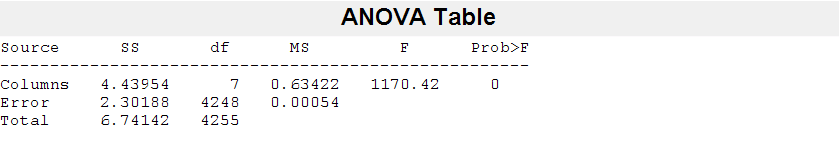

p = 0

tbl = 4×6 cell array
    {'Source' }    {'SS'    }    {'df'  }    {'MS'        }    {'F'         }    {'Prob>F'  }
    {'Columns'}    {[4.4395]}    {[   7]}    {[    0.6342]}    {[1.1704e+03]}    {[       0]}
    {'Error'  }    {[2.3019]}    {[4248]}    {[5.4187e-04]}    {0×0 double  }    {0×0 double}
    {'Total'  }    {[6.7414]}    {[4255]}    {0×0 double  }    {0×0 double  }    {0×0 double}


stats = struct with fields:
    gnames: {8×1 cell}
         n: [532 532 532 532 532 532 532 532]
    source: 'anova1'
     means: [0.2852 0.1639 0.2115 0.2444 0.2141 0.2118 0.2293 0.2355]
        df: 4248
         s: 0.0233


[p,tbl,stats] = anova1(Mean_values_conditions,groupnames)

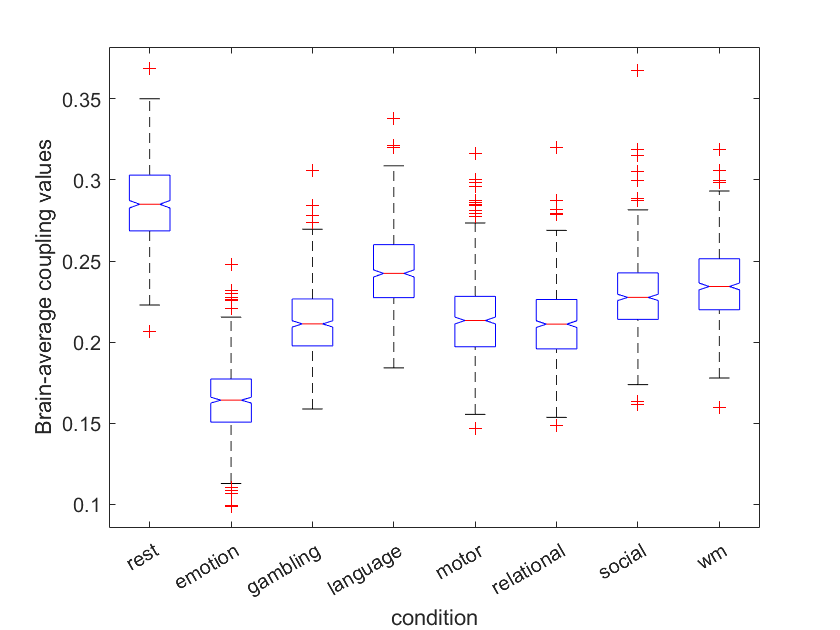

xlabel('condition')
ylabel('Brain-average coupling values')

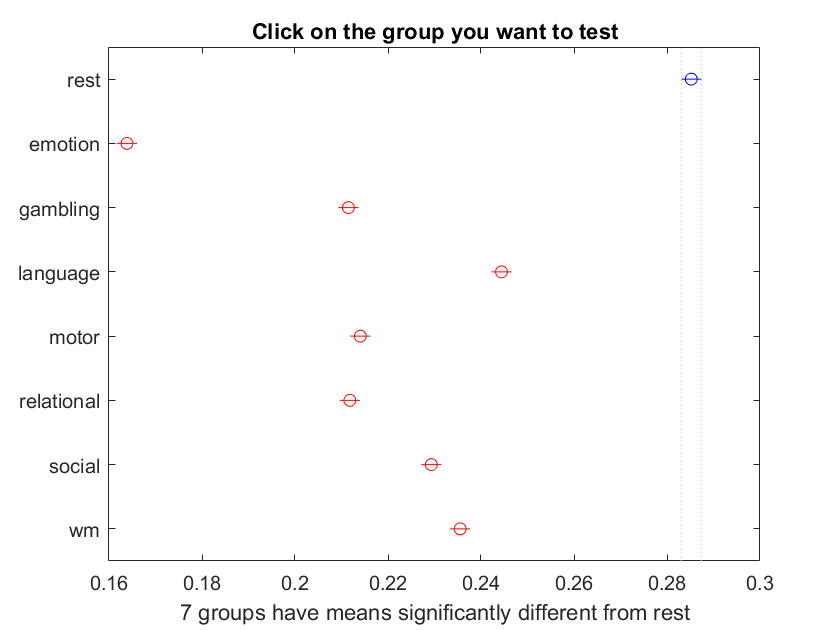

c =     1.0000    2.0000    0.1170    0.1214    0.1257         0
    1.0000    3.0000    0.0694    0.0737    0.0781         0
    1.0000    4.0000    0.0365    0.0408    0.0451         0
    1.0000    5.0000    0.0668    0.0712    0.0755         0
    1.0000    6.0000    0.0691    0.0734    0.0777         0
    1.0000    7.0000    0.0516    0.0559    0.0602         0
    1.0000    8.0000    0.0454    0.0497    0.0540         0
    2.0000    3.0000   -0.0519   -0.0476   -0.0433         0
    2.0000    4.0000   -0.0849   -0.0805   -0.0762         0
    2.0000    5.0000   -0.0545   -0.0502   -0.0459         0


gnames = 8×1 cell array
    {'rest'      }
    {'emotion'   }
    {'gambling'  }
    {'language'  }
    {'motor'     }
    {'relational'}
    {'social'    }
    {'wm'        }


[c,~,~,gnames] = multcompare(stats)

table = array2table(c,"VariableNames",["Group A", "Group B", "Lower Limit", "A-B", "Upper Limit", "P-value"])

table = 28×6 table
    Group A    Group B    Lower Limit        A-B        Upper Limit    P-value
    _______    _______    ___________    ___________    ___________    _______

       1          2          0.11703         0.12136       0.12569           0
       1          3         0.069412        0.073738      0.078063           0
       1          4         0.036488        0.040814      0.045139           0
       1          5         0.066843        0.071169      0.075495           0
       1          6         0.069097        0.073423      0.077749           0
       1          7         0.051581        0.055907      0.060233           0
       1          8         0.045376        0.049702      0.054028           0
       2          3        -0.051949       -0.047623     -0.04329

**5. Run Repeated-measures ANOVA **

data = Mean_values_conditions

data =     0.2574    0.1629    0.1963    0.2325    0.2059    0.2054    0.2137    0.2308
    0.2461    0.1717    0.1829    0.2549    0.2036    0.2005    0.2210    0.2187
    0.2882    0.1587    0.2187    0.2426    0.2079    0.2256    0.2185    0.2355
    0.2511    0.1167    0.1652    0.2051    0.1820    0.1740    0.1858    0.2012
    0.2935    0.1780    0.2269    0.2319    0.2006    0.1835    0.2373    0.2551
    0.3211    0.1587    0.2077    0.2673    0.2151    0.2071    0.2185    0.2521
    0.2782    0.1454    0.2057    0.2091    0.1844    0.1966    0.1738    0.2201
    0.2617    0.2082    0.2028    0.2378    0.1933    0.2126    0.2338    0.2414
    0.2855    0.1274    0.1980    0.2688    0.1830    0.1989    0.2257    0.2100
    0.2749    0.1513    0.1853    0.2506    0.1798    0.2252    0.1970    0.2122


subjects = (1:size(data,1))';  % Subject IDs

% Convert to table format
T = array2table(data, 'VariableNames', {'rest','emotion','gambling','language','motor','relational','social', 'wm'});
T.Subjects = subjects;

% Define Table
numbers = [1; 2; 3; 4; 5; 6; 7; 8]

numbers =      1
     2
     3
     4
     5
     6
     7
     8


Infotable = array2table(numbers, 'VariableNames', {'Condition'})

Infotable = 8×1 table
    Condition
    _________

        1    
        2    
        3    
        4    
        5    
        6    
        7    
        8    



% Define the repeated-measures model
rm = fitrm(T, 'rest-wm ~ 1', 'WithinDesign', Infotable);

% Perform repeated-measures ANOVA
ranovatbl = ranova(rm)

ranovatbl = 2×8 table
                             SumSq      DF       MeanSq        F       pValue    pValueGG    pValueHF     pValueLB  
                             ______    ____    __________    ______    ______    ________    ________    ___________

    (Intercept):Condition    4.4395       7       0.63422    2091.1       0          0           0       2.8045e-186
    Error(Condition)         1.1273    3717    0.00030329                                                           



% Display results
disp(ranovatbl)

                             SumSq      DF       MeanSq        F       pValue    pValueGG    pValueHF     pValueLB  
                             ______    ____    __________    ______    ______    ________    ________    ___________

    (Intercept):Condition    4.4395       7       0.63422    2091.1       0          0           0       2.8045e-186
    Error(Condition)         1.1273    3717    0.00030329                                                           



% Perform post-hoc tests
multcompare(rm, 'Condition')

ans = 56×7 table
    Condition_1    Condition_2    Difference      StdErr        pValue        Lower        Upper  
    ___________    ___________    __________    __________    __________    _________    _________

         1              2           0.12136      0.0012005    5.9881e-08      0.11772        0.125
         1              3          0.073738      0.0011872    5.9881e-08     0.070139     0.077336
         1              4          0.040814      0.0012684    5.9881e-08     0.036969     0.044658
         1              5          0.071169      0.0012919    5.9881e-08     0.067253     0.075085
         1              6          0.073423      0.0012523    5.9881e-08     0.069628     0.077219
         1              7          0.055907      0.